Setup

format compact
clearvars
clc

Càrrega de variables

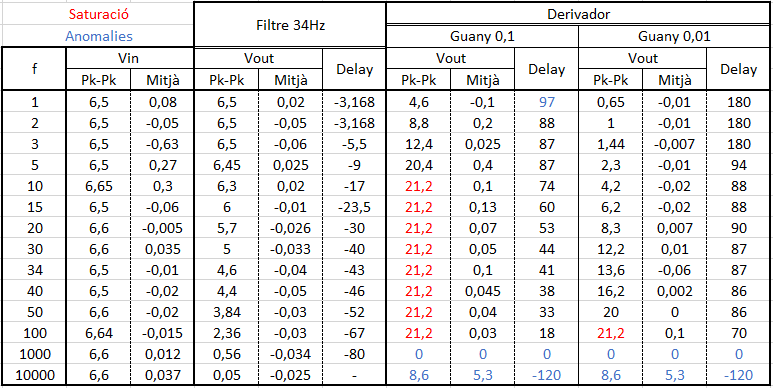

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 12);

% Specify sheet, range, names and types
opts.Sheet = "Bodes Filtre i Derivador";
opts.DataRange = "B6:M19";
opts.VariableNames = ["f", "VinPkPk", "VinMitja", "VFilter34PkPk", "VFilter34Mitja", "FilterDelay", "VKd01PkPk", "VKd01Mitja", "VKd01Delay", "VKd001PkPk", "VKd001Mitja", "VKd001Delay"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data, convert and clean up
DadesBode = readtable("..\Dades en Llaç obert.xlsx", opts, "UseExcel", false);
DadesBode = table2array(DadesBode);
xfreq = DadesBode(:,1);
clear opts

Bode del filtre passabaixos de 34Hz

figure();
ydat = 20*log10(DadesBode(:,4)./DadesBode(:,2));
semilogx(xfreq, ydat);
ylabel('Guany [dB]');
xlabel('Freqüència [Hz]');
%title('Bode empíric del filtre passabaixos de 34Hz');
titol='Bode empíric del filtre passabaixos de 34Hz';
axis([0 10000 -100 40]);
hold on;
xcutoff = spline(ydat(3:end), xfreq(3:end), -3);
fprintf('The cutoff frequency is %.1f Hz', xcutoff);

The cutoff frequency is 34.0 Hz

line(xcutoff*[1 1], [-100 40], 'LineStyle', ':');
line([1 xcutoff xfreq(end)], [0 0 -2.5*20], 'LineStyle', '-.');
fill([1, 1, 3, 3], [40, -100, -100, 40], 'b', 'FaceAlpha', 0.1, 'LineStyle', 'none');
yyaxis right;
plot(xfreq, DadesBode(:,6));
axis([0 10000 -100 40]);
ylabel('Desfasament [º]');
legend('', 'Freq. de tall', 'Guany teòric', 'Zona de treball');
hold off;

%set(gcf,'units','pixels','position',[0,0,1920,963]);
% exportgraphics(gcf, 'BodeFiltre34.png');
scale = 1

scale = 1

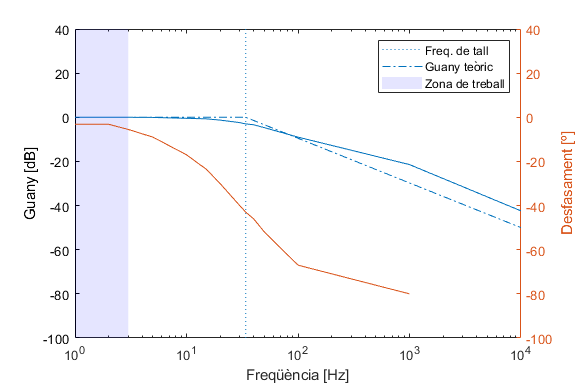

set(gcf,'units','pixels','position',[0,0,576/scale,384/scale]);
%exportgraphics(gcf, ['../Tests/Generats/', titol, '.png']);
hold off;

Bode del derivador amb Kd = 0.1

figure();
ydat = 20*log10(DadesBode(1:(end-2),7)./DadesBode(1:(end-2),2));
semilogx(xfreq(1:(end-2)), ydat);
ylabel('Guany [dB]');
xlabel('Freqüència [Hz]');
title('Bode empíric del derivador per a Kd = 0.1');
axis([0 100 -50 30]);
hold on;
xcutoff = interp1(ydat(1:5), xfreq(1:5), -3, 'linear');
fprintf('The cutoff frequency is %.1f Hz', xcutoff);

The cutoff frequency is 1.0 Hz

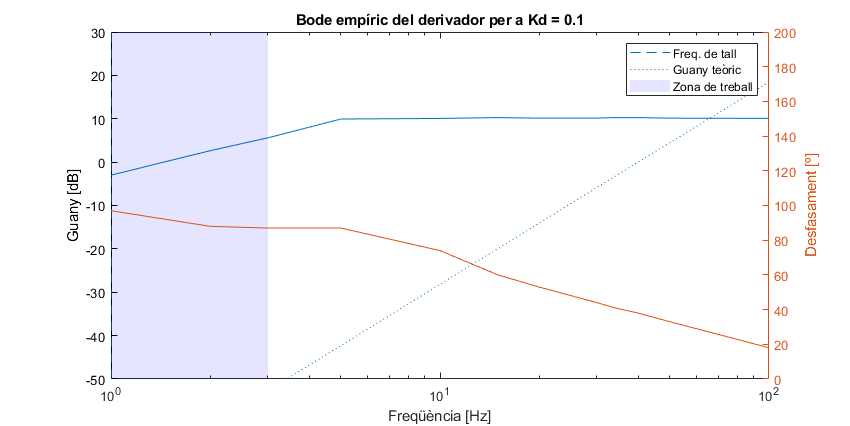

line(xcutoff*[1 1], [-50 30], 'LineStyle', '--');
line([1 40 160 6.4e2 1e6], [-75 0 20*log10(25) 20*log10(25) 0], 'LineStyle', ':'); % Bode ideal, Queda fora del gràfic (Treballem segur en regió derivadora)
fill([1, 1, 3, 3], [40, -100, -100, 40], 'b', 'FaceAlpha', 0.1, 'LineStyle', 'none');
yyaxis right;
plot(xfreq(1:(end-2)), DadesBode(1:(end-2),9));
axis([0 100 0 200]);
ylabel('Desfasament [º]');
legend('', 'Freq. de tall', 'Guany teòric', 'Zona de treball');
hold off;

set(gcf,'units','pixels','position',[0,0,1920,963]);
% exportgraphics(gcf, 'BodeKd01.png');

Bode del derivador amb Kd = 0.01

figure();
ydat = 20*log10(DadesBode(1:(end-2),10)./DadesBode(1:(end-2),2));
semilogx(xfreq(1:(end-2)), ydat);
ylabel('Guany [dB]');
xlabel('Freqüència [Hz]');
title('Bode empíric del Derivador per a Kd = 0.01');
axis([0 100 -50 30]);
hold on;
xcutoff = interp1(ydat, xfreq(1:(end-2)), -3, 'linear');
fprintf('The cutoff frequency is %.1f Hz', xcutoff);

The cutoff frequency is 11.4 Hz

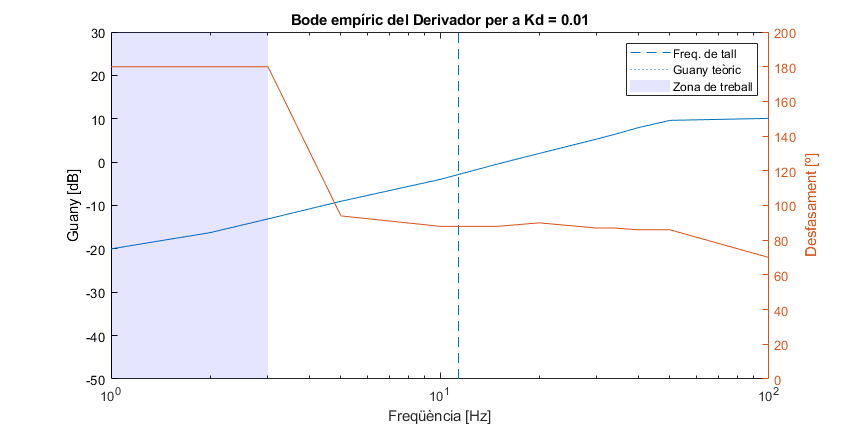

line(xcutoff*[1 1], [-50 30], 'LineStyle', '--');
line([4e2 16e2 6.4e2 1e6], [0 20*log10(25) 20*log10(25) 0], 'LineStyle', ':'); % Bode ideal, Queda fora del gràfic (Treballem segur en regió derivadora)
fill([1, 1, 3, 3], [40, -100, -100, 40], 'b', 'FaceAlpha', 0.1, 'LineStyle', 'none');
yyaxis right;
plot(xfreq(1:(end-2)), DadesBode(1:(end-2),12));
axis([0 100 0 200]);
ylabel('Desfasament [º]');
legend('', 'Freq. de tall', 'Guany teòric', 'Zona de treball');
hold off;

set(gcf,'units','pixels','position',[0,0,1920,963]);
% exportgraphics(gcf, 'BodeKd001.png');

Diagrama de bode del derivador

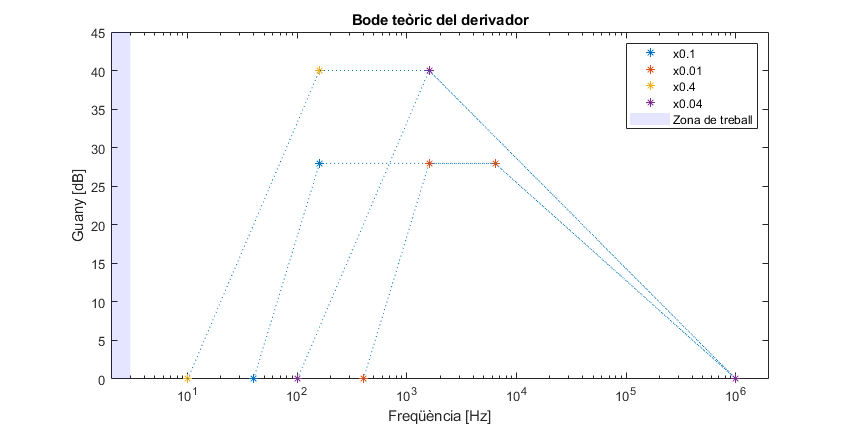

% Rin (Fix) | Cf (Fix)
% Cin (Multiplicador, x0.1 1uF - x0.01 100nF)
% Rf (Variable, 25k per cada 1 de guany (1 -> 25k, 3 -> 75k) 

% ParamMat = [ % Cin Rf
%     1e-6 25e3
%     1e-7 25e3
%     1e-6 100e3
%     1e-7 100e3
%     ];

ParamMat = [ % Cin Rf
    1e-7 25e3
    1e-7 25e3
    ];

Rin = 1e3;
Cf = 1e-9;

figure();
for i=1:size(ParamMat, 1)
    
    Cin = ParamMat(i,1);
    Rf = ParamMat(i,2);

    G = 20*log10(abs(Rf/Rin));
    f0 = 1/(Cin*Rf);
    f1 = 1/(2*pi*Rin*Cin);
    f2 = 1/(2*pi*Rf*Cf);
    f3 = 1/(Cf*Rin);
    
    semilogx([f0 f1 f2 f3], [0 G G 0], '*');
    hold on;
    line([f0 f1 f2 f3], [0 G G 0], 'LineStyle', ':');

end

fill([1, 1, 3, 3], [45, 0, 0, 45], 'b', 'FaceAlpha', 0.1, 'LineStyle', 'none');
xlabel('Freqüència [Hz]');
ylabel('Guany [dB]');
title('Bode teòric del derivador');
axis([2 2e6 0 45]);
legend('x0.1','','x0.01','','x0.4','','x0.04', '', 'Zona de treball')
hold off;

set(gcf,'units','pixels','position',[0,0,1920,963]);
% exportgraphics(gcf, 'BodeKdTeoric.png');